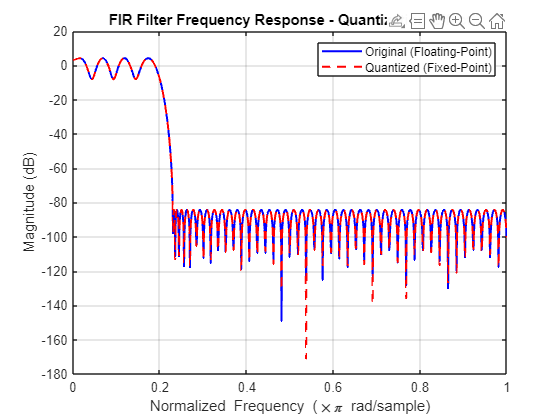

% FIR Filter Design and Export to SystemVerilog (Binary and Decimal Outputs)
clc; clear;

% Filter Specifications
N = 102; % Number of filter taps
Fpass = 0.2; % Passband edge (normalized)
Fstop = 0.23; % Stopband edge (normalized)
W = [1 10^(80/20)]; % Stopband attenuation weighting

% Design FIR Filter (Parks-McClellan algorithm)
h = firpm(N-1, [0 Fpass Fstop 1], [1 1 0 0], W);

% Convert Coefficients to Fixed-Point Using `fi` (32-bit Q31 Format)
h_fixed = fi(h, true, 24, 23); % Signed, 32-bit word length, 31 fractional bits

% Frequency Response Comparison
[H, w] = freqz(h, 1, 1024);                % Floating-point filter
[Hq, wq] = freqz(double(h_fixed), 1, 1024); % Quantized filter (convert back to double for freqz)

% Plot Frequency Response
figure;
plot(w/pi, 20*log10(abs(H)), 'b', 'LineWidth', 1.5); hold on;
plot(wq/pi, 20*log10(abs(Hq)), 'r--', 'LineWidth', 1.5);
grid on;
xlabel('Normalized Frequency (\times\pi rad/sample)');
ylabel('Magnitude (dB)');
legend('Original (Floating-Point)', 'Quantized (Fixed-Point)');
title('FIR Filter Frequency Response - Quantization Effect');


% === Save Fixed-Point Coefficients in Binary Format ===
binary_file = fullfile('fir_coeffs_binary.mem');
fid_binary = fopen(binary_file, 'w');
for i = 1:N
    % Access and convert fixed-point data to 32-bit signed binary
    fixed_value = int32(h_fixed.data(i) * 2^23); % Scale to Q31 manually
    binary_value = dec2bin(typecast(fixed_value, 'uint32'), 24); % Convert to binary
    binary_value = binary_value(end-23:end); % Truncate to 24 bits
    fprintf(fid_binary, '%s\n', binary_value); % Write binary values to file
end
fclose(fid_binary);
disp(['Fixed-point coefficients (binary) saved to: ', binary_file]);

Fixed-point coefficients (binary) saved to: fir_coeffs_binary.mem



% === Save Fixed-Point Coefficients in Decimal Format ===
decimal_file = fullfile('fir_coeffs_decimal.mem');
fid_decimal = fopen(decimal_file, 'w');
for i = 1:N
    % Access and save decimal representation of fixed-point data
    fixed_value = int32(h_fixed.data(i) * 2^23); % Scale to Q31 manually
    fprintf(fid_decimal, '%d\n', fixed_value); % Write decimal values to file
end
fclose(fid_decimal);
disp(['Fixed-point coefficients (decimal) saved to: ', decimal_file]);

Fixed-point coefficients (decimal) saved to: fir_coeffs_decimal.mem
